% Load audio file
[audio, Fs_audio] = audioread('1.wav');

% Load sine tone
[sine_tone, ~] = audioread('Carrion-sinetone.wav');

% Ensure duration is in samples
duration_samples = 5 * Fs_audio;

% Combine audios
combined_audio = audio + sine_tone;

% Play the resulting audio
sound(combined_audio, Fs_audio);

% Save to WAV file
filename = 'Carrion-speechchirp.wav';
audiowrite(filename, combined_audio, Fs_audio);

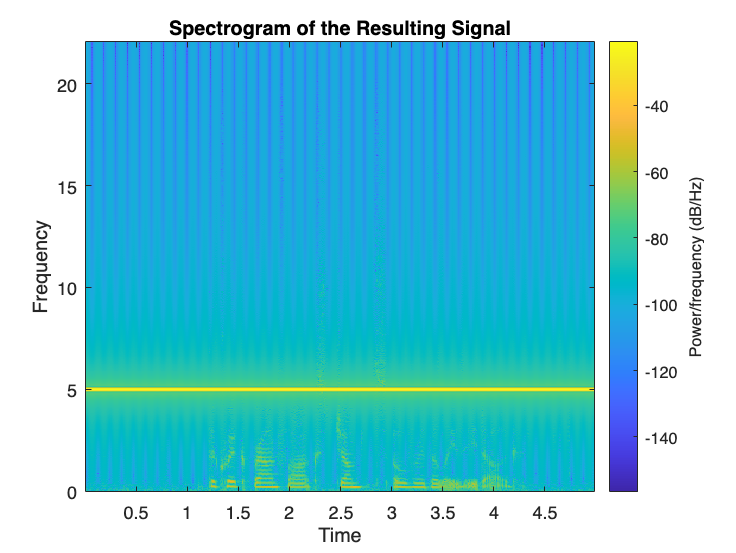


% Plot the spectrogram
figure;
spectrogram(combined_audio, 1024, 512, [], Fs_audio, 'yaxis');
title('Spectrogram of the Resulting Signal');
xlabel('Time');
ylabel('Frequency');

% Save spectrogram
saveas(gcf, 'combined_sound_files_spectrogram.png');